# Lab 3: OFDM Modulation

Kristtiya Guerra and Utsav Gupta

clc; clear all; close all;

#### Parameters

% Creating X_k - Randomly choose between 1 and -1
N_Training = 16;    % Sets of Training Symbols 
N_XData = 84;       % Sets of True Symbols 
Bits_per_sym = 64;  % Bits per symbol
size_training_data = Bits_per_sym*N_Training;       % Size of Training Data - 16 sets of 64 bits: 1024
size_X = Bits_per_sym*N_XData;                      % Size of data - 84 sets of 64 bits: 5376 bits

#### Generating Random Data to Transmit

Create Data and Training Data

range = [-1 1]; % List of wanted values: 
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); % Creates Training Data
message = [X_train ; X_k]; %Combines data

#### IDFT - Takes inverse discrete fourier tranform of data

Add Cyclic Prefix after each ifft

Len_CP = 16; %Length of Cyclic Prefix
n_data = N_Training + N_XData; % Calculates amount of sets of d-bit data chunks from original data - 100
tx_data = zeros(8000,1); %Empty vector for data to be transmitted


for x_time = 1:1:n_data
    Data_x_n = message(1 + 64*(x_time-1):x_time*64); %Extracts data set n_data - 64 bits
    Data_X_n = ifft(fftshift(Data_x_n));  %Obtains the ifft of the data: Frequency to Time- 64 bits
    %test_recovery = fft(Data_X_n); % 
    cyclic_prefix = Data_X_n(49:end); % Obtains the last 16 bits of the data
    %recoverprefix = fft(cyclic_prefix);
    Prefix_w_data = [cyclic_prefix ; Data_X_n];%Concatonate the cyclic prefix to the data set - 80 bits
    %test_recovery1 = fft(Prefix_w_data); %Time to frequency
    %test_woutpre = fft(Prefix_w_data(17:end));
    tx_data(1+80*(x_time-1):80*(x_time)) = Prefix_w_data;%Append data into the tx_data vector
end

#### Transmitting Data through nonflat channel function

Transmitting Training Data

% Transmit data through nonflat channel function
rx_data = nonflat_channel(tx_data);

Compensating for time delay

% Determine Lag in Data
[y1x1,lag1] = xcorr(rx_data,tx_data); 
[~, Index] = max(abs(y1x1));
shift = lag1(Index); %Should be 9

%Remove Extra Data
rx_data = rx_data(shift:end); %Should be 8000 bits + small excess (to be cut later)

Estimate Channel: Estimating channel for each set of 64 bits using the Training Data

%Obtain Training Data
Size_PC = 16; %Size of Cyclic Prefix
Size_Training_PC = Size_PC*N_Training + N_Training*Bits_per_sym; %1280 Bits
Training_data_rx= rx_data(1:Size_Training_PC);

Cleaned_Training_Data = zeros(N_Training*Bits_per_sym,1); %Empty vector for data without cyclic prefix

%removing cyclic prefix
for V = 1:1:16
    Set = Training_data_rx(1 + 80*(V-1):80*V);
    remove_prefix = Set(17:end);
    dat = fftshift((fft(remove_prefix))); %Move data to the frequency domain
    Cleaned_Training_Data(1+64*(V-1):64*V) = dat;
end

H_est = zeros(64,1); %Create empty vector for Channel Estimate
Original_Training= message(1:size_training_data); %Obtain original training data
Pre_H_est = zeros(N_Training*Bits_per_sym,1);

%Calculating Channel Estimate for every bit 
for Z = 1:1:N_Training*Bits_per_sym
    Channel_estimate = Cleaned_Training_Data(Z)/Original_Training(Z);
    Pre_H_est(Z) = Channel_estimate;
end

for G = 1:1:64
    %Channel_estimate = Cleaned_Training_Data./Original_Training; %
    %Estimate the channel for every subcarrier
    h_est_obtain = Pre_H_est(G:64:end);
    % Append the subcarrier channel estimates into a single channel estimate vector    
    H_est(G) = mean(h_est_obtain);
end
H_est

H_est =   -0.2867 - 0.0015i
  -0.3459 - 0.1830i
  -0.4932 - 0.3240i
  -0.6726 - 0.3760i
  -0.8812 - 0.3357i
  -1.0698 - 0.2101i
  -1.1901 - 0.0272i
  -1.2266 + 0.1911i
  -1.2068 + 0.3911i
  -1.1238 + 0.5537i


Alpha = Cleaned_Training_Data(1:64);
result = Alpha./H_est

result =    1.1633 - 0.0519i
  -0.9475 + 0.0210i
   0.9643 - 0.1375i
   1.0211 + 0.0043i
  -1.0116 + 0.0009i
   1.0247 - 0.0193i
  -1.0053 - 0.0259i
  -1.0185 - 0.0092i
   0.9851 - 0.0453i
   0.9842 + 0.0133i



stem(result);

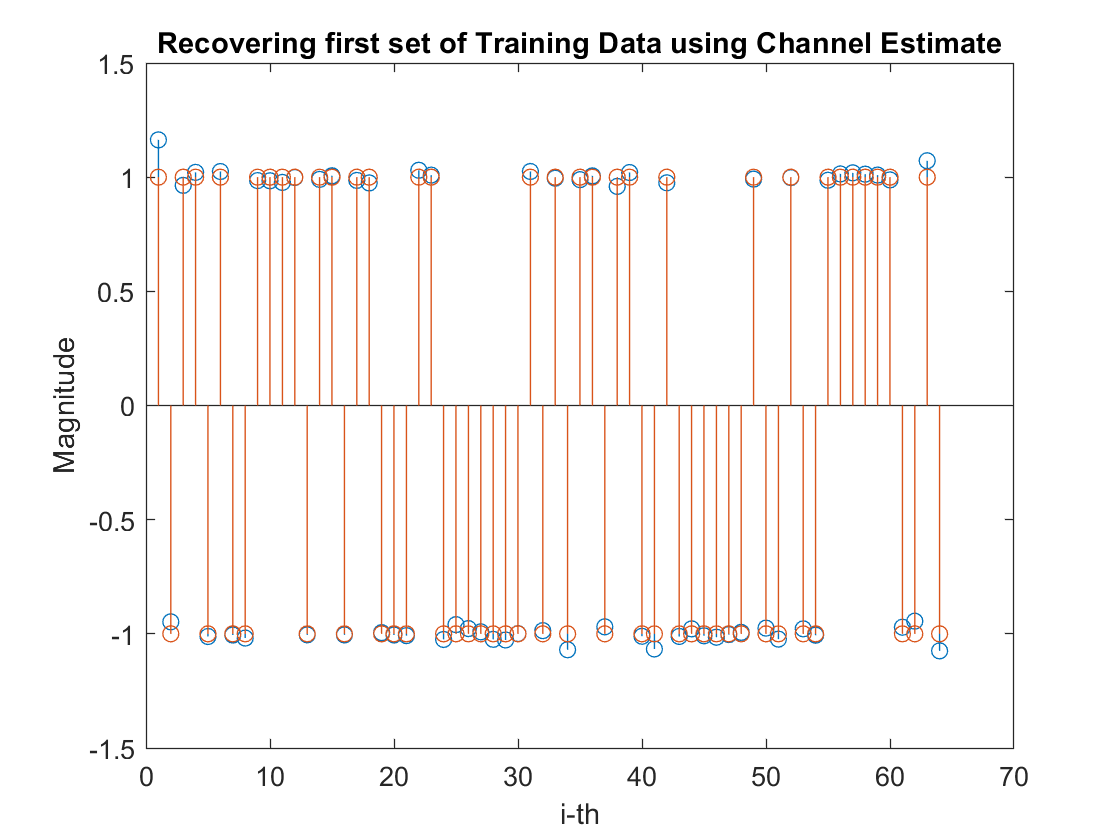

hold on
title('Recovering first set of Training Data using Channel Estimate');
stem(message(1:64));
xlabel('i-th')
ylabel('Magnitude')
hold off

Decode

Y_m = zeros(length(message),1);

for V = 1:1:n_data
    Set = rx_data(1 + 80*(V-1):80*V); %Extract n_data set of 80 bits - 80 bits
    remove_prefix = Set(17:end); %Remove Cyclic prefix and produce true data - 64 bits
    Y = fftshift(fft(remove_prefix)); %Move data to frequency domain - Move data to the frequency domain
    X_est=Y./H_est; % Divide prefix-removed Rx data by Channel Estimate vector to generate Tx estimate for every symbol
    Y_m(1 + 64*(V-1):64*V) = X_est; % Appends every est_Tx symbol to a combined est_Tx vector
end

Plot X_est

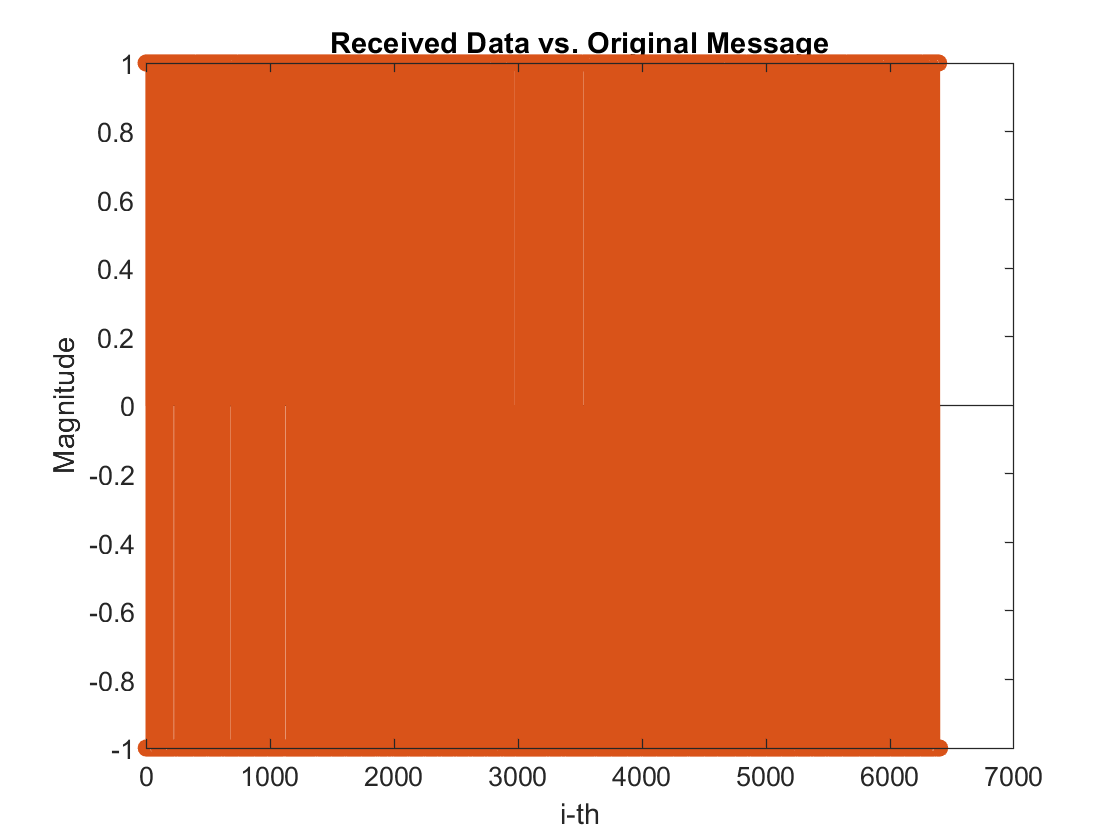

Norm_ret = real(Y_m) ./ abs(real(Y_m));

figure;
stem(real(Norm_ret));
hold on
stem(real(message));
title('Received Data vs. Original Message')
xlabel('i-th')
ylabel('Magnitude')
hold off

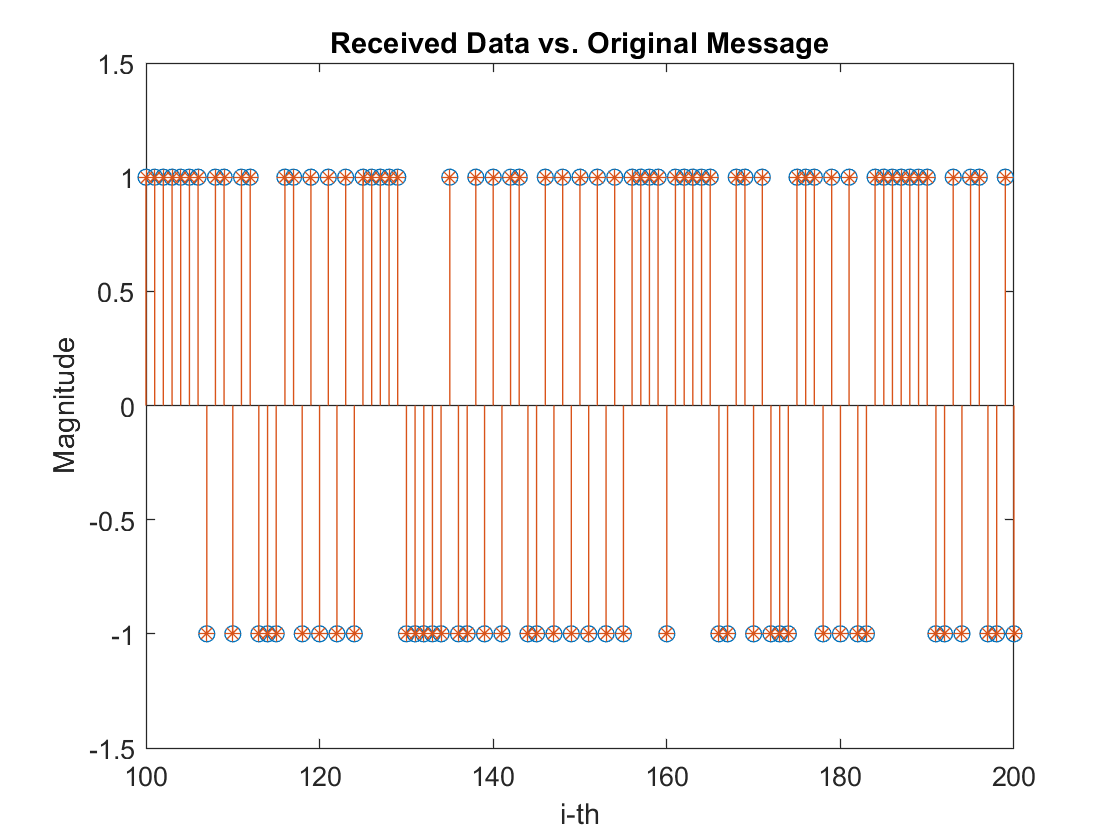


figure;
stem(real(Norm_ret));
hold on
stem(real(message),'*');
title('Received Data vs. Original Message')
xlabel('i-th')
ylabel('Magnitude')
xlim([100,200])
ylim([-1.5,1.5])
hold off

#### Transmitted Vs Received Data

% Calculating Error
diff = (message - Norm_ret)./(2*message);
Bit_Error = abs(sum(diff)/(length(diff))) *100

Bit_Error = 0

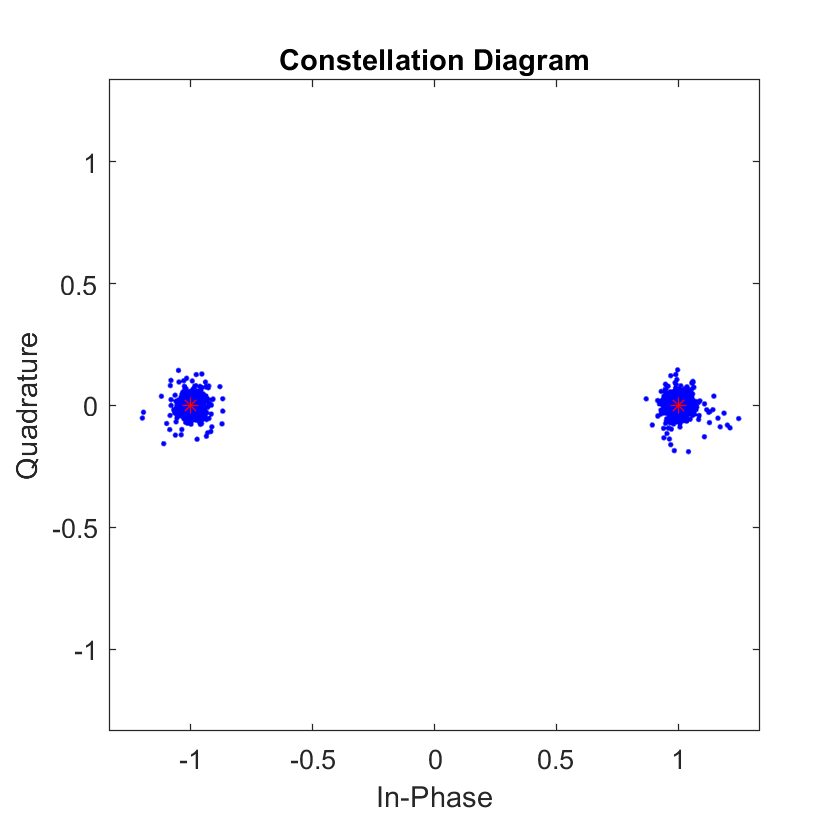

sps =2;
constDiagram = comm.ConstellationDiagram('SamplesPerSymbol',sps, ...
    'SymbolsToDisplaySource','Property','SymbolsToDisplay',100);

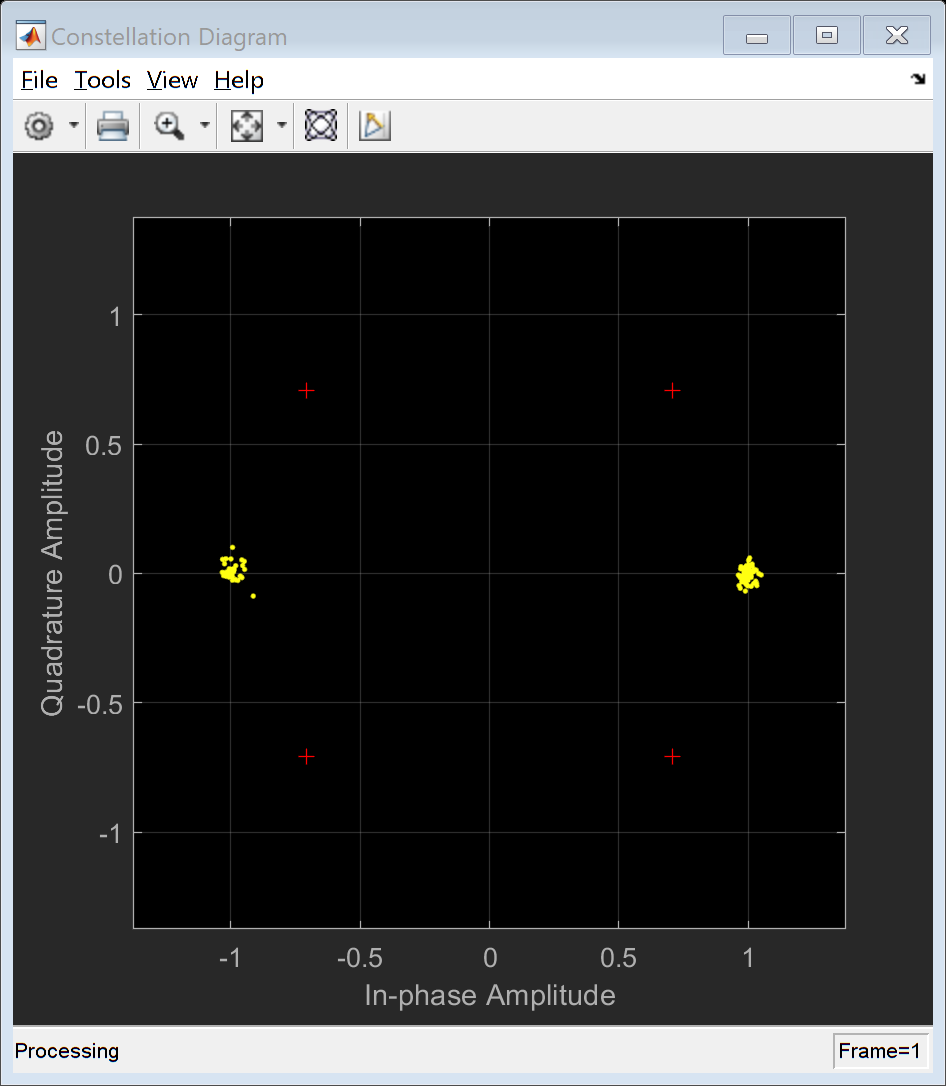

constDiagram(Y_m)